# HW 2

## Pt. 1-4

I = imread("AxonExample.png");
subplot(1,3,1), imshow(I) , title("Example Image")
subplot(1,3,2), imshow(rgb2gray(I)), title("Grayscale Image")
[row col] = size(I)

row = 389

col = 1446

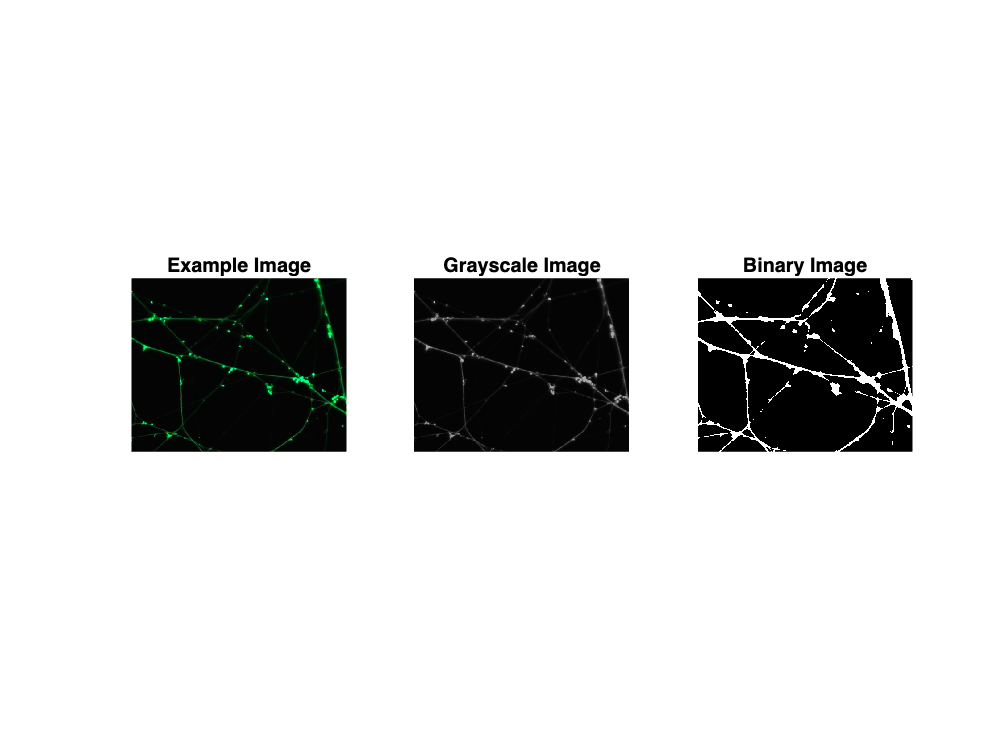

I_mean = imfilter(I, fspecial('average',[389 1446])); %averaging filter of size I
It = I-(I_mean+19); % subtract mean image (+ constant) I changed constant to decrease total number of blebs

I_binary = im2bw(It, 0);
subplot(1,3,3), imshow(I_binary), title("Binary Image")

## Pt. 5 Morphology

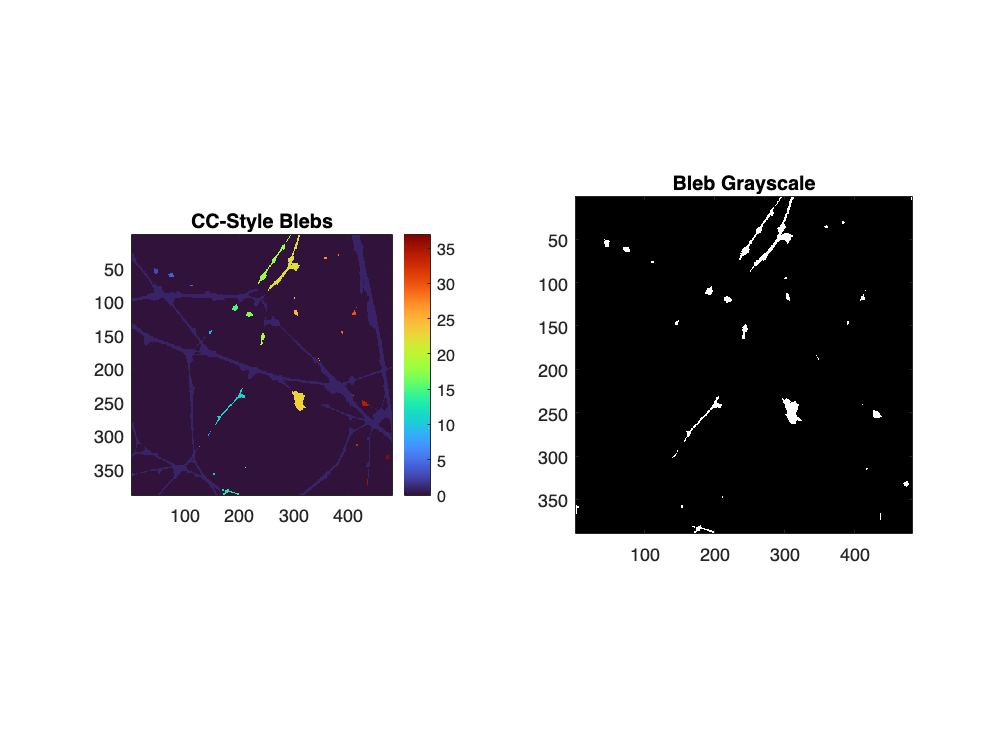

clf
% 5a.
x = bwconncomp(I_binary,8); %didnt specify neighborhood so went with 3x3 (8 surrounding voxels)
bleb = labelmatrix(x);
subplot(1,2,1), imagesc(bleb), colormap turbo, colorbar, title("CC-Style Blebs"), axis square %colorbar just indicates the total values of each color. Hence giving a value to each group
%Not sure if this is correct as the background is labeled and so is the
%long connected strings. But I can filter that out in the next step. 

% 5b.
mask = bleb>1; %individualizes the blebs, not the background or the long strings connected. 
bleb_gs = double(I).*mask;
subplot(1,2,2), imagesc(bleb_gs), title("Bleb Grayscale"), axis square

% 5c.
x.NumObjects %gives me total number of blebs. 

ans = 37

## Pt. 6 Convolution

clf
[r c] = size(bleb_gs)

r = 389

c = 1446

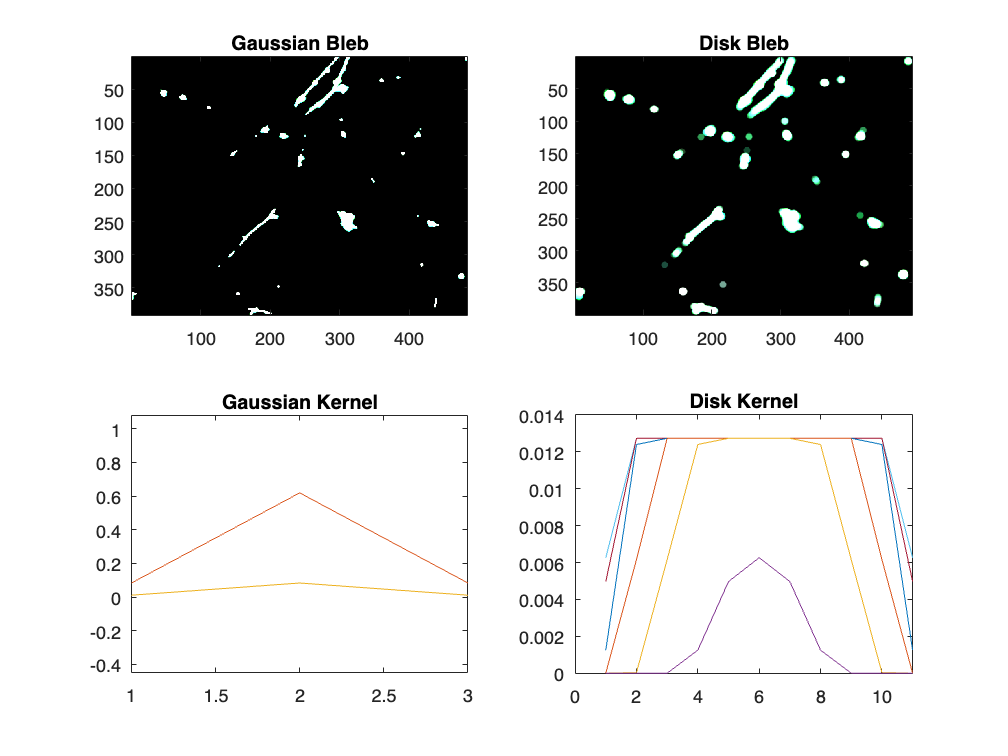

A = fspecial('gaussian'); %PSF
%B = fspecial('motion')%Motion filter, I assume how the psf goes about convolution?
bleb_conv = convn(A,bleb_gs);

subplot(2,2,3), plot(A), axis equal, title('Gaussian Kernel')
subplot(2,2,1), imagesc(bleb_conv), title('Gaussian Bleb')
%Example of different filter
B = fspecial('disk');
subplot(2,2,4), plot(B), title('Disk Kernel')
bleb_conv2 = convn(B,bleb_gs);
subplot(2,2,2), imagesc(bleb_conv2), title('Disk Bleb')

%I used two separate kernels to illustrate how the filter changes the image
%different ways. The kernel is essentially the Point spread function that
%is integrated across the image. When that changes, so does the output
%image. As you can see Gaussian adds slight variation to the original image,
%while the disk blows up each grouping much more. 